# Experimental Fluids Lab #3

**Import and Initialize Pressure Vectors**

% C:\Users\dlawson6\Desktop\Raw Lab Data\Experimental Methods Lab#3\Pressures
% Simply double click the file listed above

% Pressure data sampled at 800 Hz

% Wind off is from 0ms to ~187.5ms, or time = [1, 151]

% Steady State run time is from 400ms to 900 ms, or time = [321, 721]

% Time vector runs from 0 -> 2.5 sec over 2000 points

% Create Steady state pressure vectors

Pitot_SS = Pitot(321:721, 1);
Static3_SS = Static3(321:721, 1);
Static4_SS = Static4(321:721, 1);

Bias = 2; % Pressure transducer bias of +2 mBar
% Bias_pitot = mean(Pitot(1:151, 1)); % Pitot probe bias taken from wind-off (mBar)
% Bias_stat3 = mean(Static3(1:151, 1)); % Static port #3 bias taken from wind-off (mBar)
% Bias_stat4 = mean(Static4(1:151, 1)); % Static port #4 bias taken from wind-off (mBar)

P_o2 = (mean(Pitot_SS + Bias)) / 1000 % Pitot Probe mean pressure over steady state run time (Bar)

P_o2 = 1.8532

P_stat3 = (mean(Static3_SS + Bias) ) / 1000; % Static port #3 mean pressure over steady state run time (Bar)
P_stat4 = (mean(Static4_SS + Bias) )/ 1000; % Static port #4 mean pressure over steady state run time (Bar)
P_stat = (P_stat3 + P_stat4) / 2 % Averaged Static Pressure (Bar)

P_stat = 0.3115


P_ratio_vec = (Pitot_SS + Bias) ./ (((Static3_SS + Bias) + (Static4_SS + Bias)) / 2); % Pressure ratio Vector
P_stat_vec = ((Static3_SS + Bias) + (Static4_SS + Bias)) / 2;
P_o2_vec = Pitot_SS + Bias;

cd 'C:\Users\dlawson6\Desktop\Matlab Files\Experimental Methods'
%cd '/Users/dan/Documents/GitHub/Matlab-Files/Experimental Methods'

**Plot Pressure Ratio vs Time**

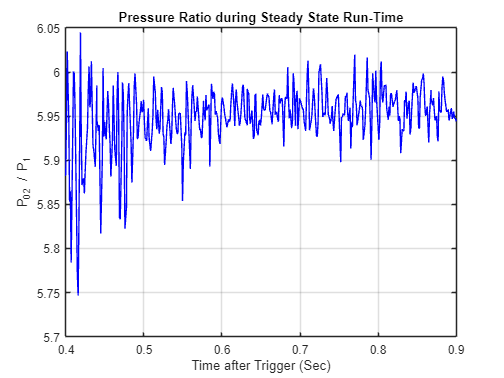

figure
plot(time(321:721),P_ratio_vec,'b')
hold on

title('Pressure Ratio during Steady State Run-Time')
xlabel ('Time after Trigger (Sec)')
ylabel ('P_02 / P_1')
grid on
xlim([0.4 0.9]);

hold off

**Find Mean and STD Via Correlation Analysis**

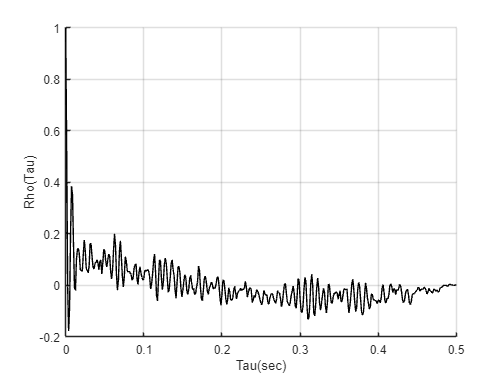

% Use code from class slides

P_fsamp = 800;
[rho,lags] = xcorr(P_ratio_vec - mean(P_ratio_vec),'coeff');

figure
hold on

plot(lags/P_fsamp, rho, '-k');
grid on
xlim([0 0.5])
ylabel('Rho(Tau)')
xlabel('Tau(sec)')

hold off


tcorr = 0.05; % Estimated Tcorr value taken from Correlation analysis

D_samp = 1 / tcorr; % Downsample frequency from Tcorr value

samp_ratio = round(P_fsamp / D_samp); % Ratio of sampling rates

P_down = downsample(P_ratio_vec, samp_ratio); % downsampled Pressure Ratio
P1_down = downsample(P_stat_vec, samp_ratio); % downsampled Static Pressure 
P_o2_down = downsample(P_o2_vec, samp_ratio); % downsampled Pitot Pressure 

T_down = linspace(0.4, 0.9,length(P_down));

% Correlation Errors

corr_std = std(P_down) % mBar STD

corr_std = 0.0397

corr_error_P_ratio = t_value(0.9, 10) * (corr_std / sqrt(11)); % Nu = N - 1, where N is our sample count
P_ratio_vec_mean = mean(P_ratio_vec); %Bar

corr_std_P1 = std(P1_down) % mBar STD

corr_std_P1 = 4.5447

corr_error_P1 = t_value(0.9, 10) * (corr_std_P1 / sqrt(11)) % Nu = N - 1, where N is our sample count

corr_error_P1 = 2.4836

P_stat_mean = mean(P1_down); % Bar

corr_std_P_o2 = std(P_o2_down) % mBar STD

corr_std_P_o2 = 27.8126

corr_error_P_o2 = t_value(0.9, 10) * (corr_std_P_o2 / sqrt(11)) % Nu = N - 1, where N is our sample count

corr_error_P_o2 = 15.1990

P_o2_mean = mean(P_o2_down); % Bar

fprintf('Correlated Mean = %.3f +/- %.3f', P_ratio_vec_mean, corr_error_P_ratio) 

Correlated Mean = 5.950 +/- 0.022

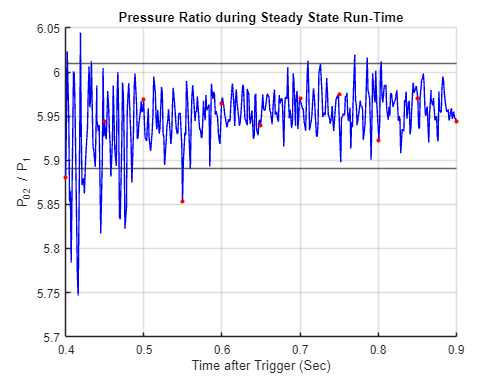


% Replot Pressure Trace with Downsampled Pressure
figure
hold on

plot(time(321:721),P_ratio_vec,'b')
plot(T_down,P_down,'r.', MarkerSize=10)
title('Pressure Ratio during Steady State Run-Time')
xlabel ('Time after Trigger (Sec)')
ylabel ('P_02 / P_1')
yline([1.01*P_ratio_vec_mean 0.99*P_ratio_vec_mean])
grid on
xlim([0.4 0.9]);

hold off

**Determine Incoming Flow Mach Number Via Rayleigh Pitot Equation**

% Use the Rayleigh Pitot formula simplified for gamma = 1.4

P_o2_stat = P_o2 / P_stat % Mean pressure ratio value

P_o2_stat = 5.9500


% (P_o2 / P1) = (6*M^2 / 5)^3.5 * (6 / (7*M^2 - 1))^2.5

% Define the range of M
M = 0.7:0.005:3;

% Calculate y (P_o2 / P1) for each possible value of M
y = (6*M.^2 / 5).^3.5 .* (6 ./ (7*M.^2 - 1)).^2.5;

syms M1;
y1 = (6*M1.^2 / 5).^3.5 .* (6 ./ (7*M1.^2 - 1)).^2.5;

% Compute the derivative of y with respect to M
dy_dM = diff(y1, M1);

% Evaluate the derivative at M1

M1_p = M(273) % M(xxx) where xxx is the array index that matches closest to the calculated (P0_2 / P_Static)

M1_p = 2.0600


derivative_value = double(subs(dy_dM, M1, M1_p));

disp(['The derivative of y at M = ', num2str(M1_p), ' is: ', num2str(derivative_value)]);

The derivative of y at M = 2.06 is: 5.2756


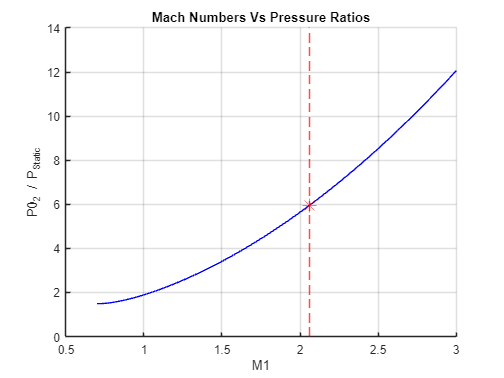


% Plot the equation
figure
hold on

plot(M, y, 'b-');
xlabel('M1');
ylabel('P0_2 / P_Static');
title('Mach Numbers Vs Pressure Ratios');
grid on;

plot(M1_p, y(273), 'r*', 'MarkerSize', 12)
xline(M1_p, 'r--')
% yline(P_o2_stat,'r--')

hold off

**Load Schlierren Images and Process**

% Initialize cell array to store images
images = cell(400, 1);

% MAC os File directory
%cd '/Users/dan/Desktop/Lab Data/Experimental Fluids Lab #3/Schlieren Images'

% Windows/PC File directory
cd 'C:\Users\dlawson6\Desktop\Raw Lab Data\Experimental Methods Lab #3\Images'

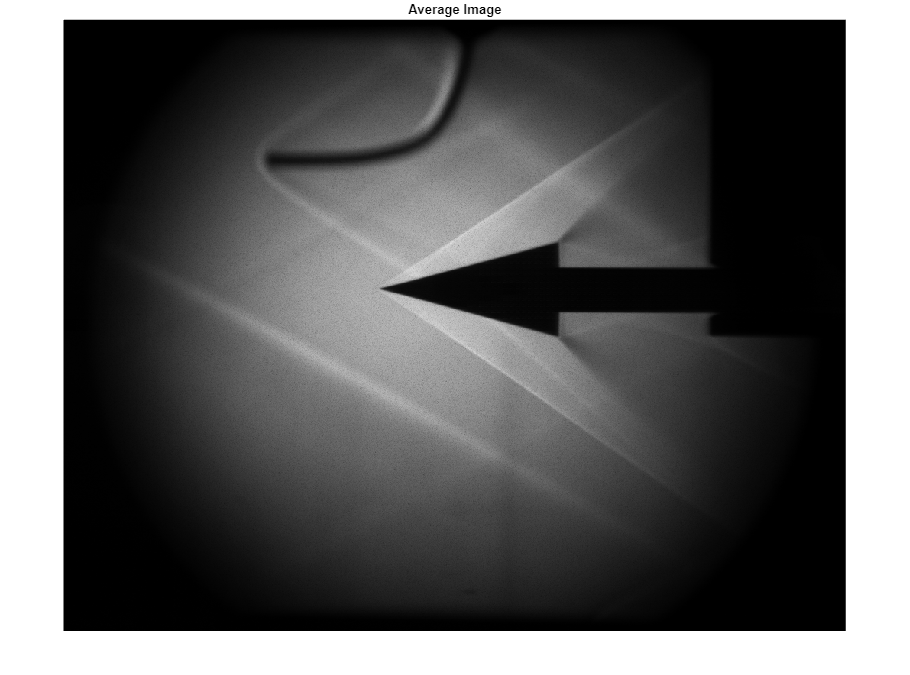

% Create array of .tif image files
for i = 1:401

    x = i + 419;
    filename = sprintf('im_4150%03d.tif', x);
    img = imread(filename);
    images{i} = img;

end

% Load Wind Off Image

filename = sprintf('_No_Flow Image.tif');
zero_img = imread(filename);

% Initialize sum of images
sum_image = zeros(size(images{1}));

% Sum each image file
for i = 1:numel(images)
    sum_image = sum_image + double(images{i});
end

% Initialize No-Flow image
zero = double(zero_img);

% Calculate the average image
average_image = uint16((sum_image - zero) / numel(images));

% Display final image
imshow(average_image);
title('Average Image');


% Save the average image
imwrite(average_image, 'average_image.tif');


% Determine Mach number using angles measured from Schlierren images

angle_pitot_MW = deg2rad(36); % Angle of Mach wave produced by pitot tube

angle_cone_shock = deg2rad(33); % Angle of Oblique Shock produced by cone

angle_lip_MW = deg2rad(29); % Angle of Mach Wave produced by test section lip

M1_MW = 1 / sin(angle_pitot_MW)

M1_MW = 1.7013


M1_lip = 1 / sin(angle_lip_MW)

M1_lip = 2.0627


M1_cone = 2.07

M1_cone = 2.0700


% Weighted average Mach Number and Error (hand calc)

M1_avg = 2.05

M1_avg = 2.0500


Error_M1 = 0.01

Error_M1 = 0.0100

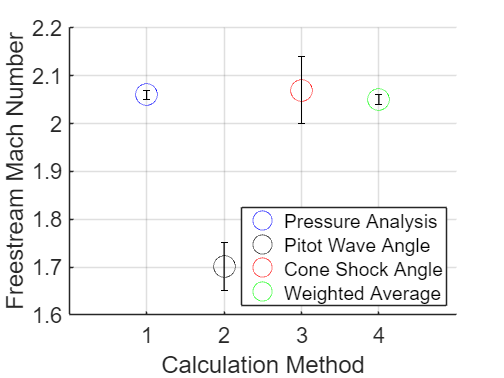

% Final Plot

x = 18;
xx = 30;

error_M1_p = 0.01;
error_M1_MW = 0.05;
error_M1_cone = 0.07;
error_M1_avg = 0.01;

figure

hold on

plot(1, M1_p, 'bo', MarkerSize=x)
plot(2, M1_MW,'ko', MarkerSize=x)
plot(3, M1_cone,'ro',MarkerSize=x)
plot(4, M1_avg, 'go',MarkerSize=x)

errorbar(1, M1_p, error_M1_p, 'k', 'LineWidth', 1)
errorbar(2, M1_MW, error_M1_MW, 'k', 'LineWidth', 1)
errorbar(3, M1_cone, error_M1_cone, 'k', 'LineWidth', 1)
errorbar(4, M1_avg, error_M1_avg, 'k', 'LineWidth', 1)

ylabel('Freestream Mach Number',FontSize=xx)
xlabel('Calculation Method',FontSize=xx)

set(gca, 'FontSize', 18)
set(gca, 'XTick', 1:4)

legend('Pressure Analysis', 'Pitot Wave Angle', 'Cone Shock Angle', 'Weighted Average',FontSize=16, Location="southeast")

xlim([0 5])
ylim([1.6 2.2])
grid on

hold off


cd 'C:\Users\dlawson6\Desktop\Matlab Files\Experimental Methods'
%cd '/Users/dan/Documents/GitHub/Matlab-Files/Experimental Methods'



















